# 离散卷积递推图例

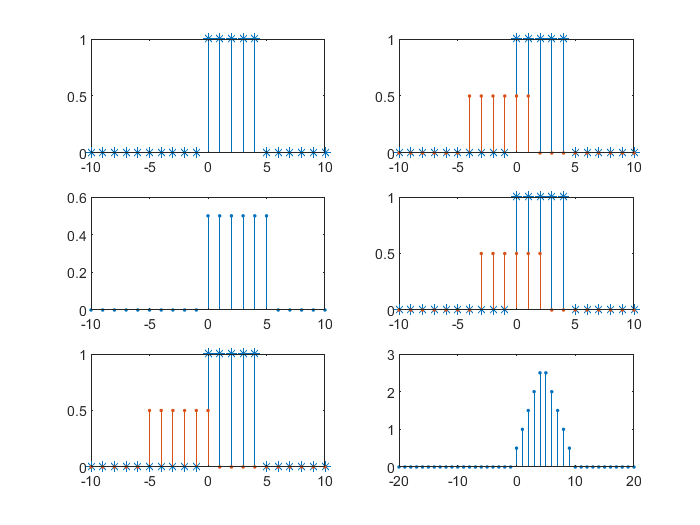

clc
clear
close all

n=(-10:10);
%x(n)序列
x=zeros(1,length(n));
x((find((n>=0)&(n<=4))))=1;
%h(n)序列
h=zeros(1,length(n));
h((find((n>=0)&(n<=5))))=0.5;
%画出x(n)
subplot(3,2,1);
stem(n,x,'*');
%画出h(n)
subplot(3,2,3);
stem(n,h,'.');

%将矩阵的列绕垂直轴进行左右翻转
%n1=fliplr(-n);
h1=fliplr(h);
subplot(3,2,5);
stem(n,x,'*');
hold on;
stem(n,h1,'.');
%集合扩展
h2=[0,h1];
h2(length(h2))=[];
%n2=n1;

subplot(3,2,2);
stem(n,x,'*');
hold on;
stem(n,h2,'.');
h3=[0,h2];
h3(length(h3))=[];
%n3=n2;

subplot(3,2,4);
stem(n,x,'*');
hold on;
stem(n,h3,'.');
n4=-n;
nmin=min(n)-max(n4);
nmax=max(n)-min(n4);
n=nmin:nmax;
y=conv(x,h);
%卷积结果
subplot(3,2,6);
stem(n,y,'.');